# Practical 5

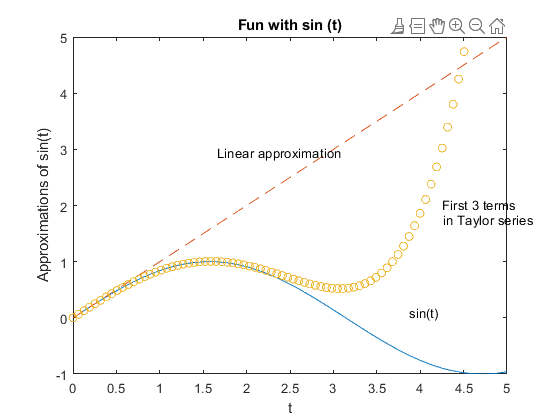

t=linspace (0, 2*pi, 100) ;
yl=sin(t) ; 
y2=t;
y3 = t - (t.^3)/6 + (t.^5)/120;
plot(t, yl , t, y2, '--', t, y3, 'o')
axis([0 5 -1 5])
xlabel('t')
ylabel('Approximations of sin(t)')
title('Fun with sin (t)')
gtext('sin(t)')
gtext('Linear approximation')
gtext('First 3 terms')
gtext('in Taylor series')

# Different 2D Plots

## fplot

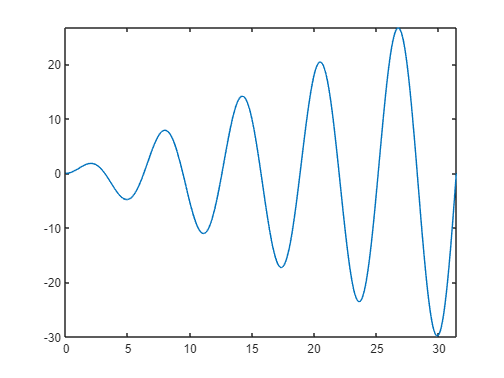

fplot('x.*sin(x)', [0 10*pi])

## semilogx

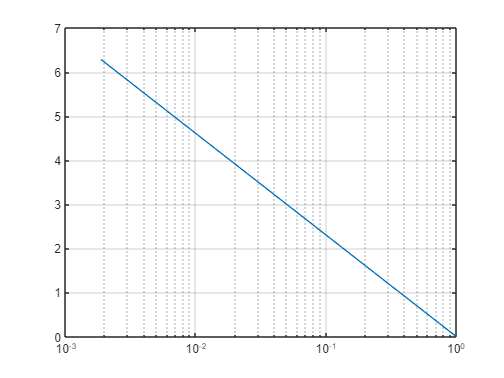

t = linspace (0,2*pi,200);
x = exp(-t) ; 
y = t;
semilogx(x,y) , grid

## semilogy

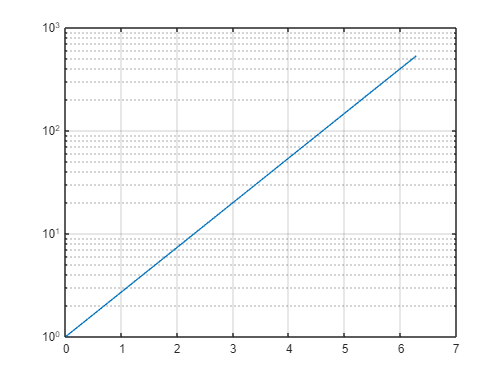

t = linspace(0,2*pi,200);
semilogy(t,exp(t))
grid

## loglog

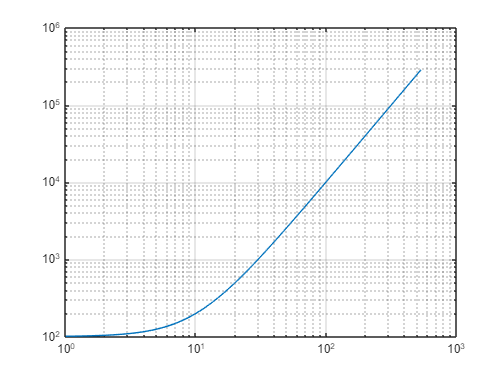

t = linspace(0,2*pi,200);
x = exp(t);
y = 100 + exp(2*t) ;
loglog(x,y) , grid

## polar

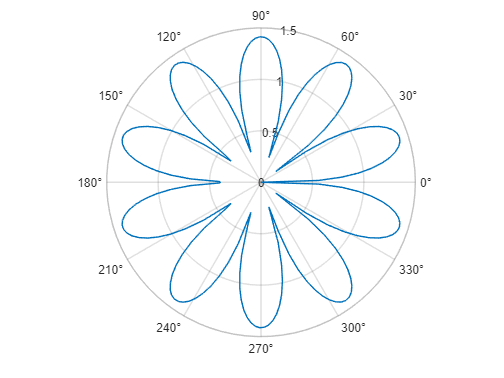

t = linspace (0,2*pi, 200) ;
r = sqrt(abs(2*sin(5*t)));
polarplot(t,r)

## fill

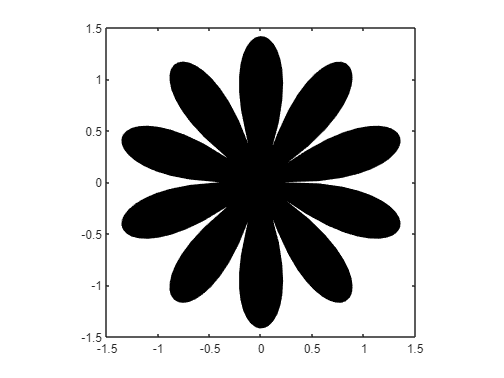

t = linspace(0,2*pi,200) ;
r = sqrt(abs(2.*sin(5*t)));
x = r.*cos(t);
y = r.*sin(t);
fill (x,y,'k'),
axis ( 'square')

## bar

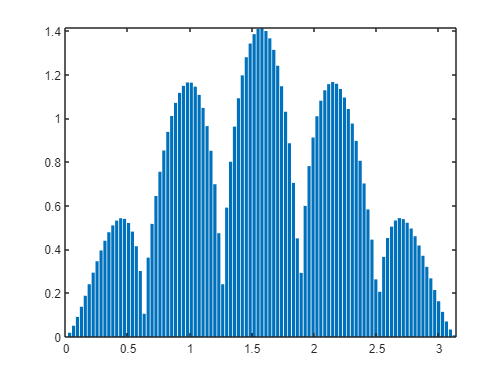

t = linspace(0,2*pi,200) ;
r = sqrt(abs(2*sin(5*t)));  
y = r.*sin(t);
bar(t,y)
axis([0 pi 0 inf]);

## errorbar

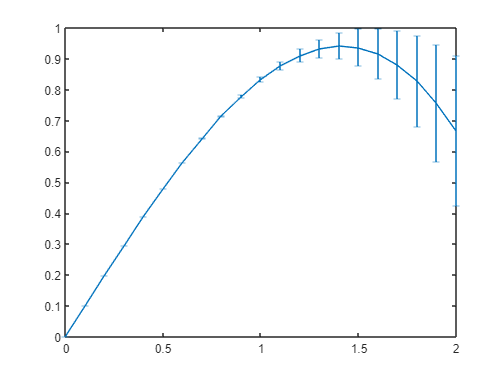

x = 0:.1:2;
aprx2 = x - x.^3/6;
er = aprx2 - sin(x);
errorbar (x, aprx2, er)

## barh

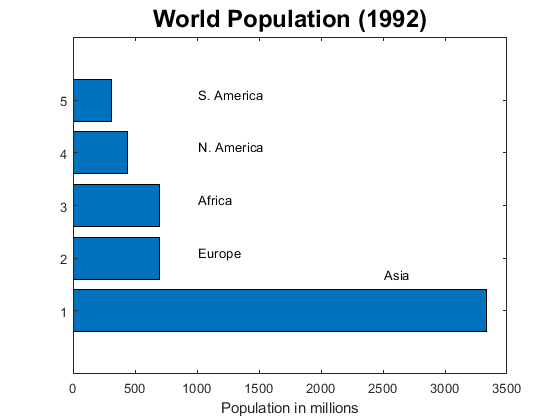

cont = char('Asia' , 'Europe' , 'Africa','N. America' , 'S. America');
pop = [3332;696;694;437;307];
barh(pop)
xlabel('Population in millions')
title('World Population (1992)','fontsize' ,18)
for i=1:5,
    gtext(cont(i,:));
end

## plotyy

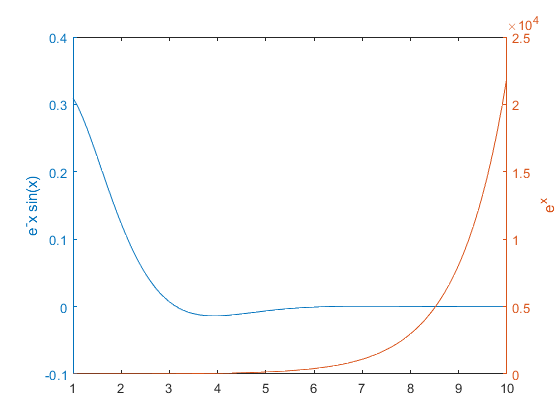

x = 1:.1:10;
yl = exp(-x).*sin(x);
y2 = exp(x) ;
Ax = plotyy(x,yl,x,y2);
hy1 = get(Ax(1),'ylabel');
hy2 = get(Ax(2),'ylabel');
set(hy1,'string', 'e^-x sin(x)');
set(hy2,'string','e^x');

## area

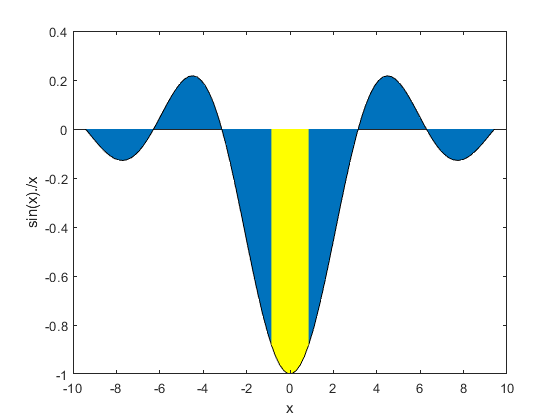

x = linspace(-3*pi,3*pi,100);
y = -sin(x)./x;
area(x,y)
xlabel('x'),ylabel('sin(x)./x')
hold on
x1 = x(46:55); y1 = y(46:55);
area(x1, y1, 'facecolor','y')
hold off

## pie

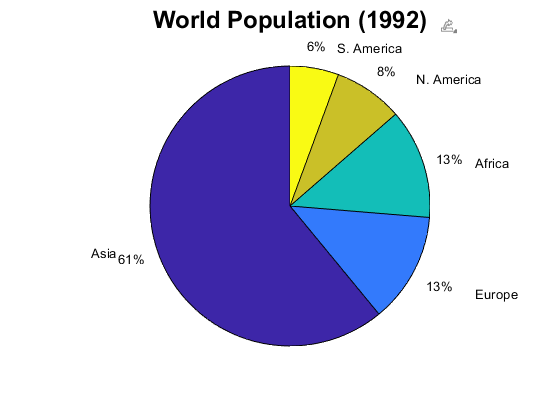

cont = char ('Asia' , 'Europe' , 'Africa', ...
    'N. America' , 'S. America') ;
pop = [3332;696;694;437;307];
pie(pop)
for i = 1:5,
    gtext (cont (i,:));
end
title('World Population (1992)','fontsize' , 18)

## hist

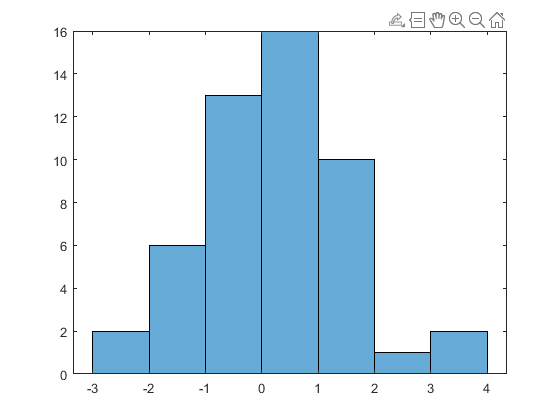

y = randn (50, 1);
histogram(y)

## stem

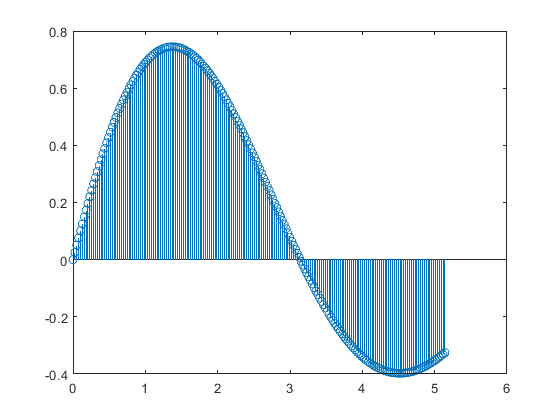

t = linspace(0,2+pi, 200) ;
f = exp(-.2*t).*sin(t);
stem(t,f)

## stairs

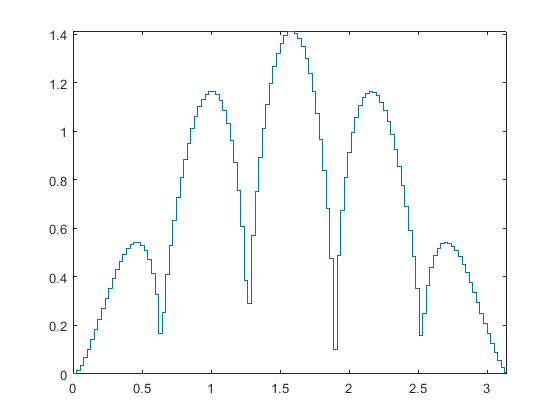

t = linspace (0, 2+pi, 200);
r = sqrt(abs(2*sin(5*t)));
y = r.*sin(t);
stairs(t,y)
axis([0 pi 0 inf]);

## compass

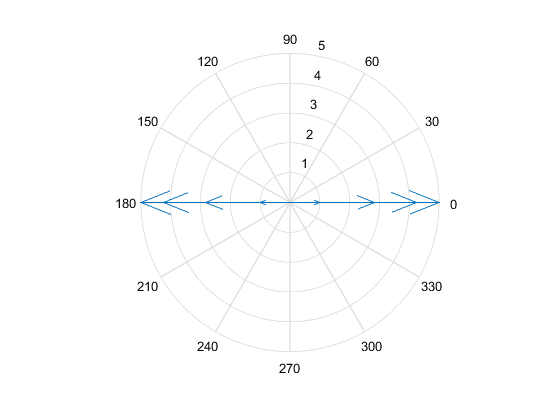

th = -pi:pi/4:pi;
zx = cos(th) ;
zy = sin(th) ;
z = zx + i*zy;
compass(z)

## comet

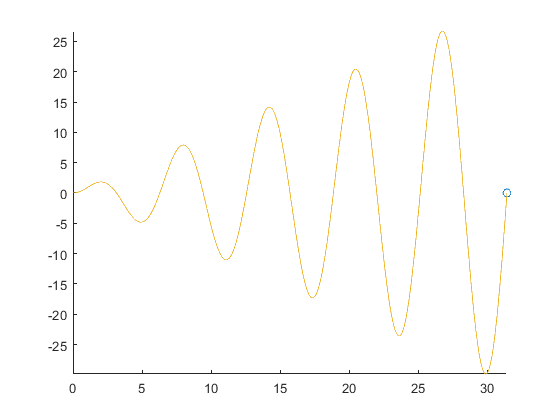

q = linspace(0, 10*pi, 2000) ;
y = q.*sin(q);
comet(q,y)

## contour

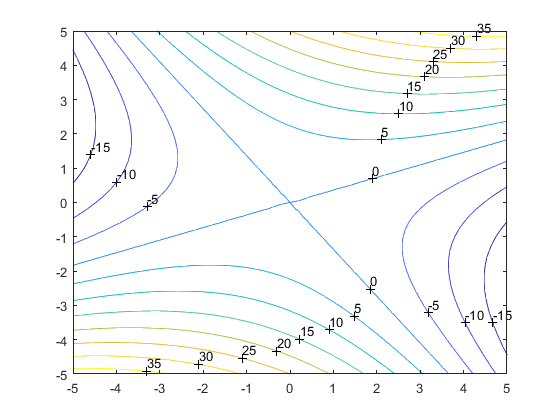

r = -5:.2:5;
[X, Y] = meshgrid(r,r);
Z = -.5*X.^2 + X.*Y + Y.^2;
cs = contour(X,Y,Z);
clabel(cs)

## quiver

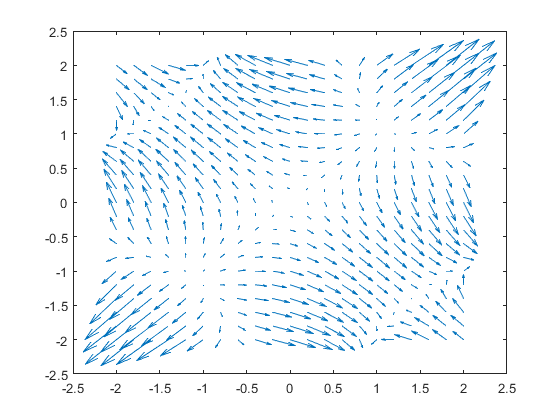

r = -2:.2:2;
[X, Y] = meshgrid(r,r);
Z = X.^2 - 5*sin(X.*Y) + Y.^2;
[dx, dy] = gradient(Z,.2,.2);
quiver(X,Y,dx,dy,2);

## pcolor

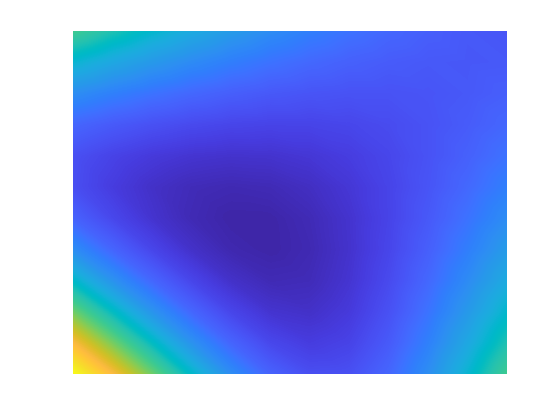

r = -2:.2:.2;
[X, Y] = meshgrid(r,r);
Z = X.^2 - 5*sin(X.*Y) + Y.^2;
pcolor(Z),axis('off')
shading interp

# Different 3D Plots

## plot3

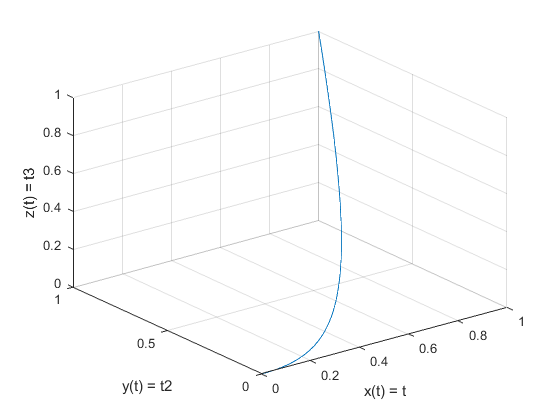

t = linspace (0, 1, 100);
x = t; y = t.^2; z = t.^3;
plot3(x, y,z), grid
xlabel ('x(t) = t')
ylabel('y(t) = t2')
zlabel ('z(t) = t3')

## fill3

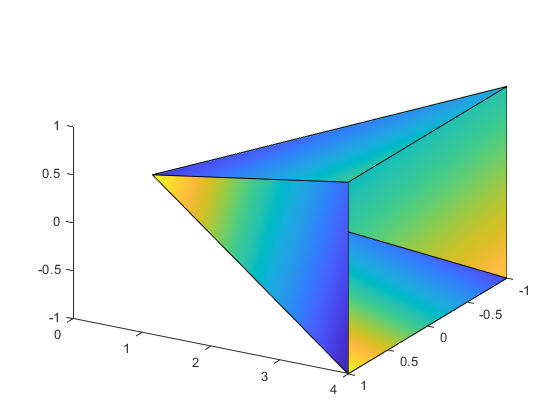

X = [0 0 0 0; 1 1 -1 1;1 -1 -1 -1] ;
Y = [0 0 0 0; 4 4 4 4;4 4 4 4];
Z = [0 0 0 0; 1 1 -1 -1;-1 1 1 -1];
fillcolor=rand(3,4);
fill3(X,Y,Z,fillcolor)
view(120, 30)

## contour3

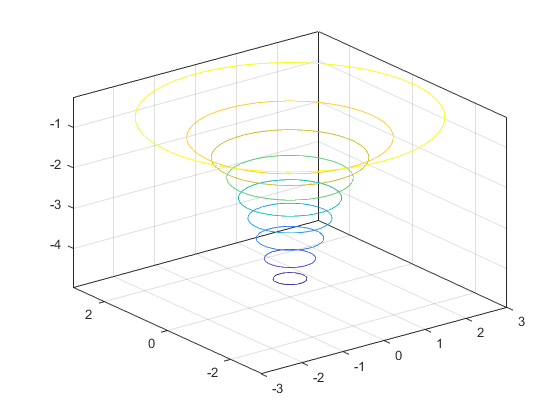

r = linspace(-3,3,50);
[x, y] = meshgrid(r,r);
z = -5./(1 + x.^2 + y.^2) ;
contour3(x,y,z)

## surf

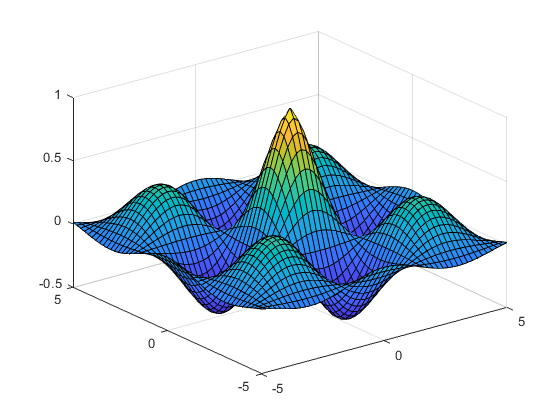

u = -5:.2:5;
[X, Y] = meshgrid(u, u) ;
Z = cos(X) .* cos(Y) .* exp(-sqrt (X.^2 + Y.^2)/4);
surf(X, Y ,Z)

## surfc

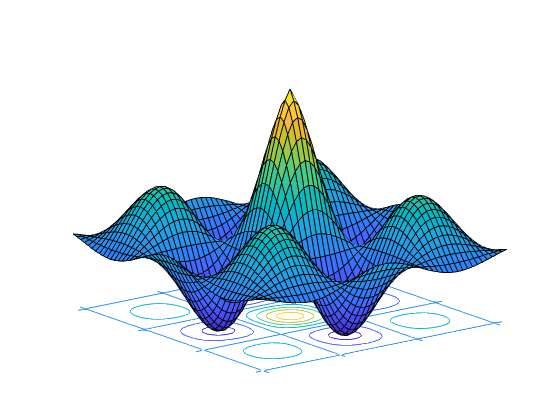

u = -5:.2:5;
[X, Y] = meshgrid(u, u) ;
Z = cos (X) .* cos(Y) .*exp (-sqrt (X.^2 + Y.^2)/4);
surfc(Z)
view(-37.5,20)
axis('off')

## surfl

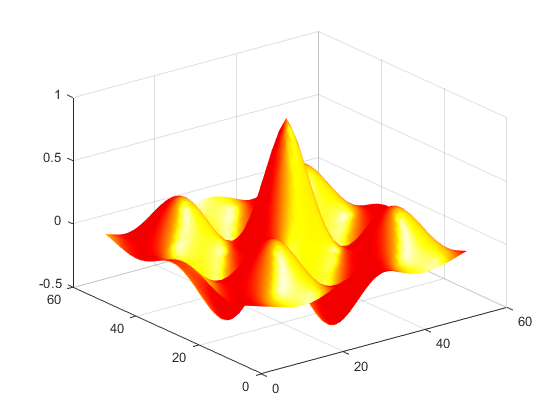

u = -5:.2:5;
[X, Y] = meshgrid(u, u);
Z = cos (X) .* cos(Y) .* exp(-sqrt (X.^2 + Y.^2)/4);
surfl(Z)
shading interp
colormap hot

## sphere

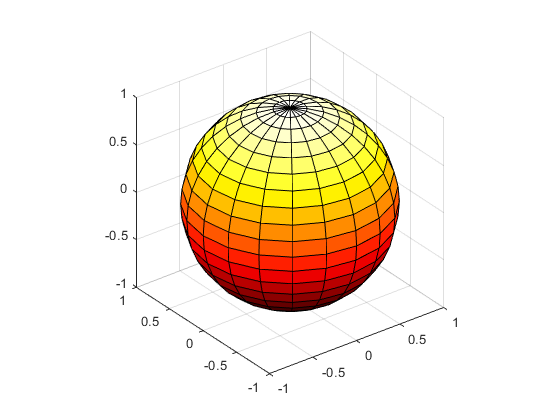

sphere (20)
axis('square')

or

[x,y,z] = sphere(20) ;
surf(x,y,z)
axis('square')

## ellipsoid

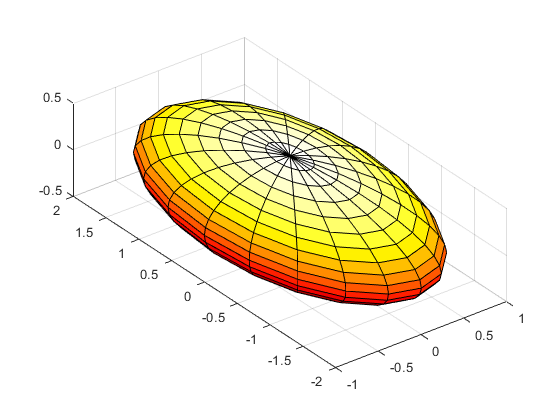

cx = 0; cy = 0; cz = 0;
rx = 1; ry = 2; rz = 0.5;
ellipsoid(cx,cy,cz,rx,ry,rz)
axis('equal')

## cylinder

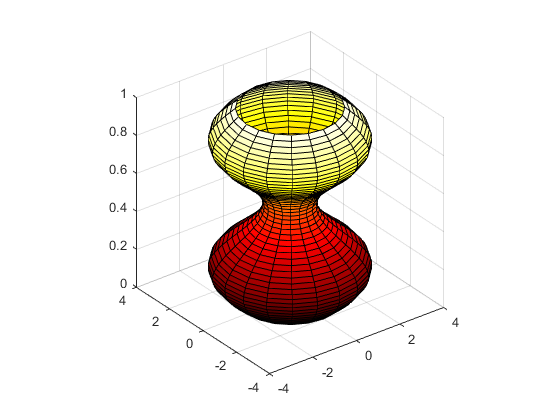

z = [0:.02:1]';
r = sin (3*pi*z) + 2;
cylinder (r), axis square

## slice

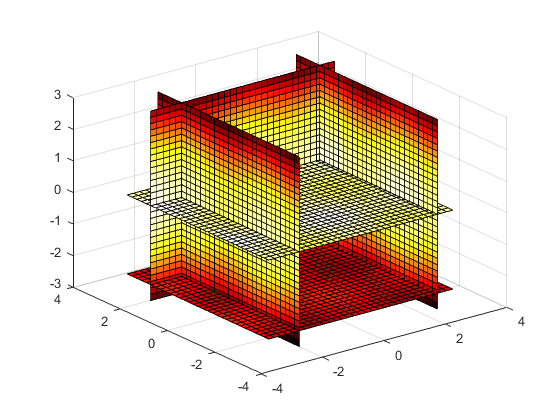

v = [-3: .2:3];
[x, y,z] = meshgrid(v,v,v) ;
f = (cos (x).^2 + sin(y).^2-z.^2);
xv = [-2 2.5]; yv = 2;
zv = [-2.5 0] ;
slice(x, y,z, f, xv, yv, zv) ;